# Problema 2

Considera el camp de velocitats eulerià


$$\vec{v} = (x^2-y^2+x) \vec{i} - (2xy+y) \vec{j}$$


**a) És cinemàticament compressible el flux?  (0.25P).**

Cal comprovar si se satisfà $\nabla \cdot \vec{v} = 0 \; \rightarrow \; \frac{\partial v_x}{\partial x} + \frac{\partial v_y}{\partial y} = 0$:  Com que $v_x = x^2 - y^2 +x$, $v_y=-2xy-y$, la divergència és $ \nabla \cdot \vec{v}=2x+1 - 2x - 1 = 0$ resulta que el flux és INcompressible

**b) Calcula la seva vorticitat (0.25P).**

$\vec{\Omega}=\nabla\times\vec{v}=\left| \matrix{ \vec{i} & \vec{j} & \vec{k} \cr \frac{\partial}{\partial x} & \frac{\partial}{\partial y} & \frac{\partial}{\partial z} \cr v_x & v_y & v_z}\right|$ = $\left| \matrix{ \vec{i} & \vec{j} & \vec{k} \cr \frac{\partial}{\partial x} & \frac{\partial}{\partial y} & 0 \cr x^2-y^2 + x & -2xy-y & 0}\right|$ = $\left[\frac{\partial}{\partial x}(-2xy-y) -\frac{\partial}{\partial y}(x^2-y^2+x) \right] \vec{k}$=  $(-2y + 2y) \, \vec{k} = 0$

**c) Calcula l'acceleració (0.5P).**


$$\vec{a}= \frac{\partial \vec{v}}{\partial t} + \vec{v} \cdot \nabla \vec{v} = \vec{v} \cdot \nabla \vec{v} $$
 

el camp de velocitats no depèn explícitament del temps i la derivada temporal és nul·la. Per tant,


$$\vec{a}= \vec{v} \cdot \nabla \vec{v} = (v_x,v_y, 0) \cdot \left(\matrix{\frac{\partial}{\partial x} \cr \frac{\partial}{\partial y} \cr 0 }\right) (v_x,v_y, 0) \;= \;  (v_x,v_y, 0) \cdot \left(\matrix{\frac{\partial v_x}{\partial x} & \frac{\partial v_y}{\partial x}  & 0 \cr \frac{\partial v_x}{\partial y} & \frac{\partial v_y}{\partial y} & 0 \cr 0 & 0 & 0}\right)$$
 
$$\Rightarrow$$



$$a_x = v_x \frac{\partial v_x}{\partial x} + v_y \frac{\partial v_x}{\partial y}$$
 


$$a_y = v_x \frac{\partial v_y}{\partial x} + v_y \frac{\partial v_y}{\partial y}$$



$$a_z = 0$$


syms x y
vx=x.^2-y.^2+x; vy=-2.*x.*y-y;
dvxdx=diff(vx,x);
dvxdy=diff(vx,y);
dvydx=diff(vy,x);
dvydy=diff(vy,y);
ax=vx*dvxdx + vy*dvxdy;
ay=vx*dvydx + vy*dvydy;
ax=simplify(ax)

$$ax = \left(2\,x+1\right)\,\left(x^{2}+x+y^{2}\right)$$

ay=simplify(ay)

$$ay = y\,\left(2\,x^{2}+2\,x+2\,y^{2}+1\right)$$

**d) Troba les línies de corrent (per integrar-la, comprova que l'equació diferencial de les línies de corrent és exacta) (0.5P).**

$\frac{dx}{v_x} = \frac{dy}{v_y}$   $\Rightarrow\frac{dx}{x^2-y^2+x} = \frac{dy}{-2xy-y}$   solució $\Rightarrow  \frac{x^3}{3} - x(y^2 + y)= C$ 


$$-(2xy+y) dx = (x^2-y^2+x)dy$$
 
$$\Rightarrow (2xy+y) dx + (x^2-y^2+x)dy =0$$



$$M(x,y) = 2xy+y=-v_y$$



$$N(x.y) = (x^2-y^2+x) = v_x$$


Com que $\frac{\partial M}{\partial y} = \frac{\partial N}{\partial x}$, es tracta d'una equació exacta, $dF = \frac{\partial M}{\partial x} dx + \frac{\partial N}{\partial y} dy = 0$ amb solució $F=cte$

$F = -\int v_y \;dx + g(y)$  $ = \int (2xy+y) \;dx + g(y)$$ = x^2y + xy + g(y)$               (d1)

$F = \int v_x \;dy + f(x)$$ = \int (x^2-y^2+x) \;dy + f(x)$$ = x^2y -\frac{y^3}{3} +xy +  f(x)$      (d2)

Aleshores $f(x)$ es com a màxim una constant,  i $g(y)=-\frac{y^3}{3} + ctnt$ $\Rightarrow F=x^2y+xy-\frac{y^3}{3}$ excepte una constant arbitrària, i la solució és la família de corbes $\Rightarrow x^2y+xy-\frac{y^3}{3} = C$  $(F= C = cntn)$

**e) Existeix la funció de corrent en aquest problema? Si és que sí, digues quina és (0.5P).**

Si el flux és incompressible, estacionari i 2D (o funció de dues coordenades només) la funció de corrent $\psi$ existeix . Al nostre problema per tant, ha de ser possible trobar $\psi$ tal que 

$v_x = \frac{\partial \psi}{\partial y}$   $\Rightarrow \psi = \int v_x \;dy + f(x)$ (la integral d2)  $ = x^2y - \frac{y^3}{3} + xy + f(x)$

$v_y = -\frac{\partial \psi}{\partial x}$  $\Rightarrow \psi = -\int v_y \;dx + g(y)$ (la integral d1) $ = x^2y + xy + g(y)$

Per tant, la funció de corrent (que queda determinada tret d'una constant) es $\psi=xy^2+xy-\frac{y^3}{3}$  i coincideix amb la $F$de l'apartat anterior. 

Observa que per obtenir les línies de corrent hem fet les mateixes integrals, i això és perquè si se satisfan les condicions d'incompressibilitat, flux estacionari i 2D, l'equació de les linies de corrent és una edo exacta!

**f) Amb MATLAB, utilitza la funció **`quiver`** per dibuixar el camp de velocitats **$\vec v$**, en la regió **$-2 \le x \le 2$**, **$0 \le y \le 2$**. Amb la comanda adequada, sobreimposa-hi les línies de corrent. Presenta el gràfic combinat del camp de velocitats amb les línies de corrent, junt amb l'escript que hagis utilitzat (0.5P).**

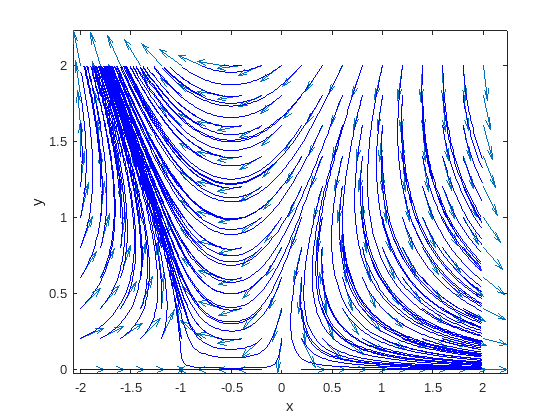

x = -2:0.2:2;
y =  0:0.2:2;
[X,Y] = meshgrid(x,y);
vx = X.^2-Y.^2+X;
vy = -(2*X.*Y+Y);
modul=sqrt(vx.^2+vy.^2);
quiver(x,y,vx./modul,vy./modul)

hold on
startX = X;
startY = Y;
streamline (X,Y,vx,vy,startX,startY);
xlabel('x'), ylabel('y')
axis tight
hold off

Alternativament, amb `streamlice`, 

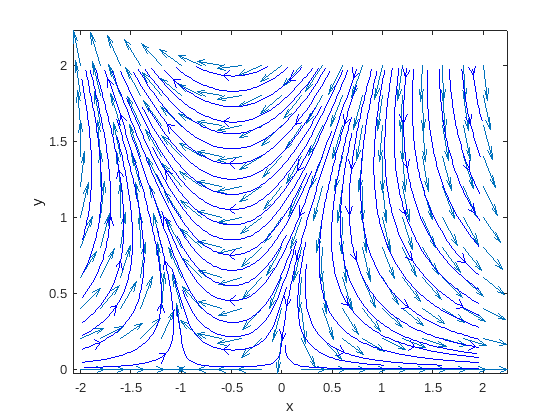

quiver(x,y,vx./modul,vy./modul)
hold on
streamslice(x,y,vx,vy)
xlabel('x'), ylabel('y')
axis tight
hold off